load('data/scaling_irs.mat');
num_irs = height(measurementData)

num_irs = 6

factors = zeros(num_irs);
ir_len = 512

ir_len = 512

start = 3300;
irs = zeros(num_irs, ir_len);



irs(1, :) = measurementData{1, 2}.Amplitude(start - 1:start+ir_len - 2).';
irs(2, :) = measurementData{2, 2}.Amplitude(start - 6:start+ir_len - 7).';
irs(3, :) = measurementData{3, 2}.Amplitude(start - 6:start+ir_len - 7).';
irs(4, :) = measurementData{4, 2}.Amplitude(start:start+ir_len - 1).';
irs(5, :) = measurementData{5, 2}.Amplitude(start:start+ir_len - 1).';
irs(6, :) = measurementData{6, 2}.Amplitude(start - 6:start+ir_len - 7).';

for i = 1:num_irs
    factors(i) = max(abs(irs(i, :)));
    irs(i, :) = irs(i, :) / factors(i);
end
% for i = 1:num_irs
%     if any([(i == 3), (ir == 2),(ir == 6)])
%         ir = measurementData{i, 2}.Amplitude(start - 6:start+ir_len - 7).';
%     else
% 
%     end
%         factors(i) = max(abs(ir));
%     irs(i, :) = ir / factors(i);
% end

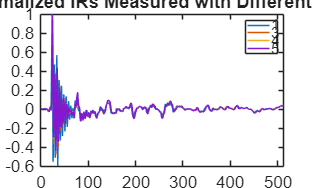

t = measurementData{1, 2}.Time(start:start+ir_len - 1).';
figure
plot(irs(1, :), 'DisplayName', string(1));
hold on;
for i = 3:5
    plot(irs(i, :), 'DisplayName', string(i));
    hold on;
end
hold off;
xlim([0, ir_len]);
legend();
title('Normalized IRs Measured with Different Gain')
xlabel('Time (s)')
ylabel('Normalized Amplitude')

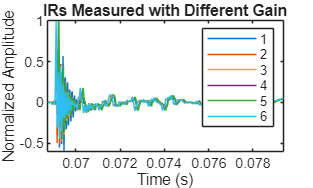

t = measurementData{1, 2}.Time(start:start+ir_len - 1).';
figure
for i = 1:num_irs
    plot(t, irs(i, :), 'DisplayName', string(i));
    hold on;
end
hold off;
xlim([t(1), t(end)]);
legend();
title('IRs Measured with Different Gain')
xlabel('Time (s)')
ylabel('Normalized Amplitude')

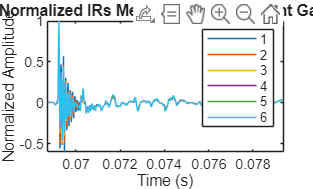

t = measurementData{1, 2}.Time(start:start+ir_len - 1).';
figure
for i = 1:num_irs
    plot(t, irs(i, :), 'DisplayName', string(i));
    hold on;
end
hold off;
xlim([t(1), t(end)]);
legend();
title('Normalized IRs Measured with Different Gain')
xlabel('Time (s)')
ylabel('Normalized Amplitude')

[old_rec, fs] = audioread('data/double_mics.wav');
[new_rec, fs] = audioread('audio_experiments/mics_nc.wav');

old_tgt = old_rec(:, 1);
old_ref = old_rec(:, 2);

new_tgt = new_rec(:, 1);
new_ref = new_rec(:, 2);


max(old_tgt)

ans = 0.0057

max(new_tgt)

ans = 0.0268

max(old_ref)

ans = 0.1188

max(new_ref)

ans = 0.5758